clc; clear all;

CP = py.importlib.import_module("CoolProp.CoolProp");



tfordamp = -20;
tkond = 35;
middel = "R134a";

underkoling = -5;
Hkond = CP.PropsSI("H","T",273.15 + tkond + underkoling,"Q",0,middel)

Hkond =           241722.392308654


Pkond = CP.PropsSI("P","T",273.15 + tkond,"Q",0,middel)

Pkond =           886980.983608352



Hfordamp = CP.PropsSI("H","T",273.15 + tfordamp,"Q",1,middel)

Hfordamp =           386554.261631309


Pfordamp = CP.PropsSI("P","T",273.15 + tfordamp,"Q",1,middel)

Pfordamp =           132734.979499223



overhedning = 5;
Hkomp = CP.PropsSI("H","T",273.15 + tfordamp + overhedning,"Q",0,middel)

Hkomp =           180137.556076574



format longG

% Kølemiddel
ps = 100;
Tfrys = 0;
Tkog = 1200;
middel = "R134a";

% for R134a
Pmin = CP.PropsSI("P","T",170, "Q", 0, middel)

Pmin =           396.167894782514


Pmax = CP.PropsSI("P","T", 374, "Q", 1, middel)

Pmax =           4042129.37699199


Plin = linspace(Pmin, Pmax, ps);


Tsat_l = zeros(size(Plin));

for i = 1:ps-1
    Tsat_l(i) = CP.PropsSI("T", "P", Plin(i), "Q", 0, middel);
end

hl = zeros(size(Plin));
hg = zeros(size(Plin));
sl = zeros(size(Plin));
sg = zeros(size(Plin));

for j = 1:ps-1
    hl(j) = CP.PropsSI("H","P",Plin(j), "Q", 0, middel);
    hg(j) = CP.PropsSI("H","P",Plin(j), "Q", 1, middel);
    sl(j) = CP.PropsSI("S","P",Plin(j), "Q", 0, middel);
    sg(j) = CP.PropsSI("S","P",Plin(j), "Q", 1, middel);
end


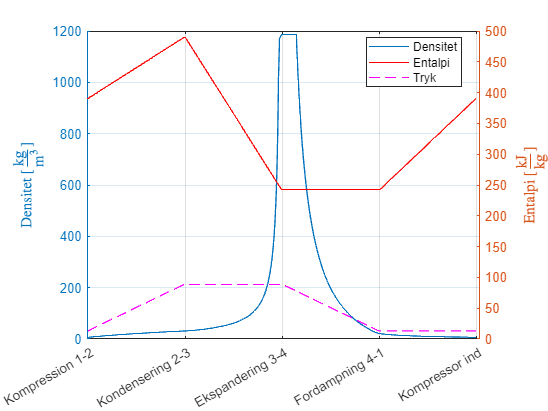

% Fra opgave

h1 = 3.904*1e5;
p1 = 1.327e5;

h2 = 4.898*1e5;
p2 = 8.868*1e5;

h3 = 2.423*1e5;
p3 = p2;

h4 = h3;
p4 = p1;

%til plot

hlin1 = linspace(h1,h2,ps-1);
hlin2 = linspace(h2,h3,ps-1);
hlin3 = linspace(h3,h4,ps-1);
hlin4 = linspace(h4,h1,ps-1);
hs = [hlin1,hlin2,hlin3,hlin4];

plin1 = linspace(p1,p2,ps-1);
plin2 = linspace(p2,p3,ps-1);
plin3 = linspace(p3,p4,ps-1);
plin4 = linspace(p4,p1,ps-1);
pps = [plin1,plin2,plin3,plin4]/1e5;

Tr134a = zeros(size(pps));


for k = 1:length(pps)
    Tr134a(k) = CP.PropsSI("T","H",hs(k),"P",pps(k)*1e5, middel);
end
Tr134a;
Trs = Tr134a-273.15;


Dr134a = zeros(size(pps));
Qr134a = zeros(size(pps));

for g = 1:length(pps)
    Dr134a(g) = CP.PropsSI("D","H",hs(g),"P",pps(g)*1e5, middel);
    Qr134a(g) = CP.PropsSI("Q","H",hs(g),"P",pps(g)*1e5, middel);
end

figure
grid()
xticks(linspace(1,396,5))
xticklabels(["Kompression 1-2","Kondensering 2-3","Ekspandering 3-4","Fordampning 4-1","Kompressor ind"])

yyaxis left
plot(Dr134a)
ylabel("Densitet [$\frac{\mathrm{kg}}{\mathrm{m^3}}$]", "Interpreter","latex")

yyaxis right
plot(hs/1e3,"r-")
ylabel("Entalpi [$\frac{\mathrm{kJ}}{\mathrm{kg}}$]","Interpreter","latex")



hold on
plot(pps*1e1,"m--")

hold off

legend("Densitet","Entalpi","Tryk","Location","best")

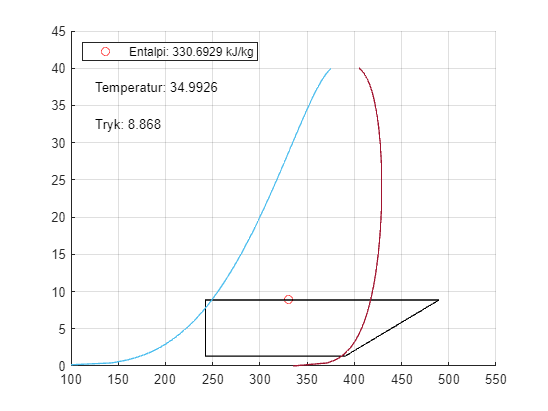

figure

for i = 1:length(hs)

    scatter(hs(i)/1e3,pps(i),"r")

    xlim([1,5.5]*1e2)

    grid("on")

    hold on

    % Kølekreds
    plot(hlin1/1e3,plin1/1e5,"k",hlin2/1e3,plin2/1e5,"k",hlin3/1e3,plin3/1e5,"k",hlin4/1e3,plin4/1e5,"k")

    % PH diagram (ikke log)
    plot(hl(1,1:end-1)/1e3,Plin(1,1:end-1)/1e5)
    plot(hg(1,1:end-1)/1e3, Plin(1,1:end-1)/1e5)

    legend("Entalpi: " + hs(i)/1e3 +" kJ/kg","Location","northwest")

    text(1.25*1e2,37.5,"Temperatur: " + Trs(i))
    text(1.25*1e2,32.5,"Tryk: " + pps(i))

    drawnow

    pause(0.05)



    hold off
end

clc; clear all;

ps = 100
x1 = linspace(50,100,ps);
y1 = linspace(2,10,ps);

x2 = linspace(100,10,ps);
y2 = linspace(10,10,ps);

x3 = linspace(10,10,ps);
y3 = linspace(10,2,ps);

x4 = linspace(10,50,ps);
y4 = linspace(2,2,ps);

%plot(x1,y1,"k")



%plot(x1,y1,"k",x2,y2,"k",x3,y3,"k",x4,y4,"k")


for i = 1:ps
    scatter(x1(i),y1(i),"r")
    hold on

    xlim([1,100])
    ylim([1,12])




    scatter(x2(i),y2(i),"r")
    scatter(x3(i), y3(i),"r")
    scatter(x4(i),y4(i),"r")

    plot(x1,y1,"k",x2,y2,"k",x3,y3,"k",x4,y4,"k")

    legend("Entalpi kompressor: " + x1(i), "Entalpi Kondensater: " + x2(i), ...
        "Entalpi EPV: " + x3(i), "Entalpi fordamper: " + x4(i),"Location","best")

    drawnow

    pause(0.05)



    hold off
end

clear all;
ps = 100;
x1 = linspace(50,100,ps);
y1 = linspace(2,10,ps);

x2 = linspace(100,10,ps);
y2 = linspace(10,10,ps);

x3 = linspace(10,10,ps);
y3 = linspace(10,2,ps);

x4 = linspace(10,50,ps);
y4 = linspace(2,2,ps);



plot(x1,y1,"k",x2,y2,"k",x3,y3,"k",x4,y4,"k")
